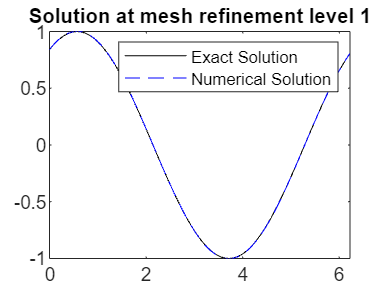

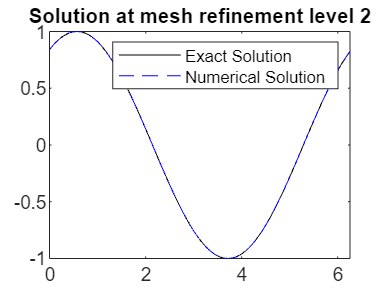

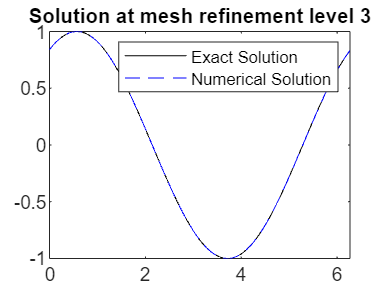

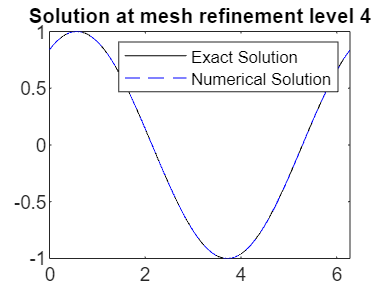

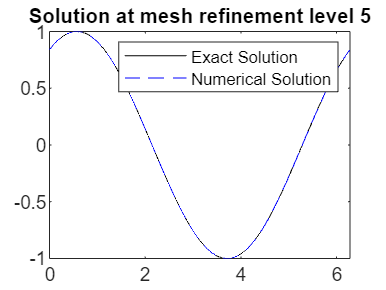

% Sanaz Hami
% 1D Linear Advection with 'fmincon' solver

% Initialization of parameters
xa = 0;
xb = 2 * pi;
T = 1;
lambda = 0.5;
v0 = @(x) sin(x);
errtab = zeros(5, 2);
m = -1; % Define lower bound
M = 1; % Define upper bound
% Main loop for mesh refinement
for kk = 1:5
% Mesh size calculation
Nx = 100 * (2 ^ (kk - 1)) - 1;
h = (xb - xa) / (Nx + 1);
k = h^2;
% Initialization of solution vector
v = zeros(1, Nx + 3);
x = linspace(xa, xb - h, Nx + 1);
v(2:Nx + 2) = v0(x);
v(1) = v(Nx + 2); % Ghost point for the right boundary
v(Nx + 3) = v(2); % Ghost point for the left boundary
% Time marching
v_new = zeros(size(v));
for ii = 1:floor(T / k)
for jj = 2:Nx + 2
v_new(jj) = v(jj) + ((k / h )/ 2) * (v(jj + 1) - v(jj - 1));
end
v_new(1) = v_new(Nx + 2);
v_new(Nx + 3) = v_new(2);
v = v_new;
end
% Final timestep
for jj = 2:Nx + 2
    v_new(jj) = v(jj) + (((T - floor(T / k) * k) / h) / 2) * (v(jj + 1) - v(jj - 1));
end
v = v_new;
% Begin optimization post-processing
% Define the objective function for the optimization
objective = @(x) norm(x - v(2:Nx+2), 2);
% Define the constraints for the optimization
Aeq = ones(1, Nx + 1); % Conservation constraint matrix
beq = sum(v(2:Nx+2)); % Conservation constraint value
lb = m * ones(Nx + 1, 1); % Lower bounds
ub = M * ones(Nx + 1, 1); % Upper bounds
% Define the options for the optimization solver
options = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');
% Solve the optimization problem
x_opt = fmincon(objective, v(2:Nx+2), [], [], Aeq, beq, lb, ub, [], options);
% Update the solution with the optimized values
v(2:Nx+2) = x_opt;
% Calculate numerical error and plot
u_exac = v0(x + T);
errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx + 2)).^2 * h));
figure; % Create a new figure for each plot
plot(x, u_exac, 'k', x, v(2:Nx + 2), 'b--');
legend('Exact Solution', 'Numerical Solution');
title(sprintf('Solution at mesh refinement level %d', kk));
end

% Compute the order of accuracy
for kk = 2:5
errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
end
format shortE;
disp(errtab)

   3.5982e-03            0
   9.0916e-04   1.9847e+00
   2.2863e-04   1.9915e+00
   5.7393e-05   1.9940e+00
   1.4377e-05   1.9971e+00

